# Shape control

## Preliminaries

The aim of this last exercise is to design a shape controller for our plasma equilibrium. This control loop is meant to control a set of plasma-wall gaps plus the position of the X-point.

We start by extracting the rows of the C matrix associated to the gaps and the x-point position

addpath ./functions
addpath ./models
addpath ./data 

modelName = fullfile(pwd,'models','SOF@18d66s_FG.mat');
model = load(modelName);

lm.A = -model.L\model.R;
lm.B =  model.L\eye(size(model.L));
lm.C =  model.C;
lm.D =  zeros(size(lm.C,1), size(lm.B,2));
lm.E = -model.L\model.LE;
lm.F =  model.F;

% Get gaps definition
r_gap = model.Input_struct.r_sens_gap;
z_gap = model.Input_struct.z_sens_gap;
t_gap = model.Input_struct.theta_sens_gap_deg;

% Choose a few gaps
% iGap = [1 5 7 9 11 16 17 18 19 29];
iGap = [1 5 7 9 16 17 18 19 29];
rg = r_gap(iGap);
zg = z_gap(iGap);
tg = t_gap(iGap);
lg = 1; 

% Gap C matrix
i_gap = get_y_idx(model.y_type,'Gap');
i_gap = i_gap(iGap);
C_gap = model.C(i_gap,:);

% X-point C matrix
i_xp = get_y_idx(model.y_type,{'Rbound','Zbound'},1);
C_xp = model.C(i_xp,:);

Here is our choice of gaps

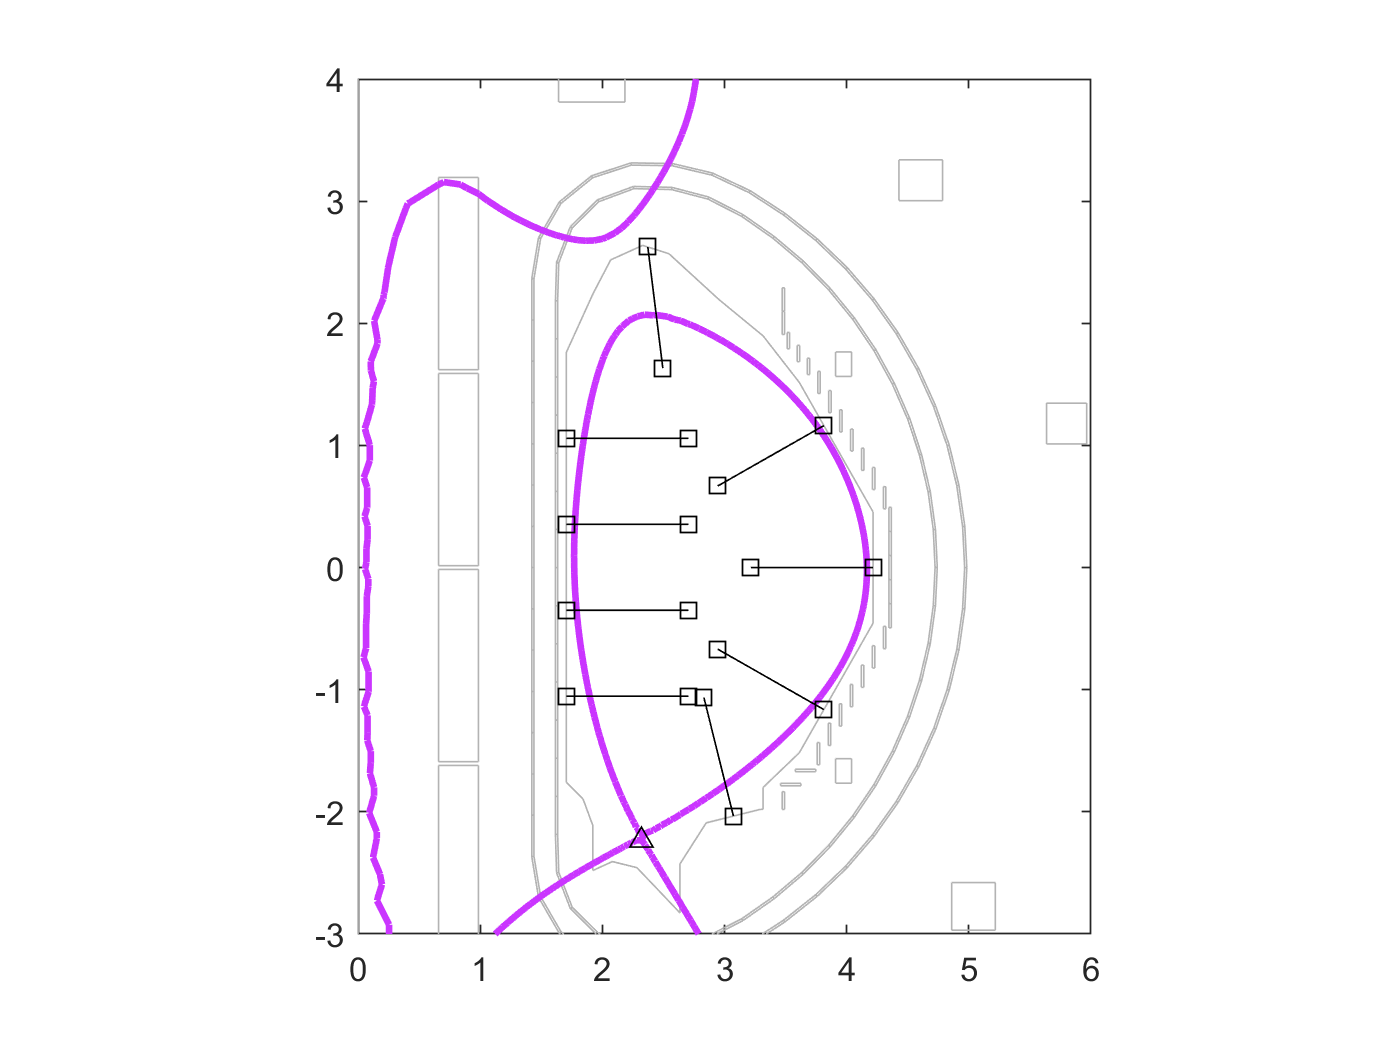

% Plot equilibrium...
figure
nnodes = size(model.Input_struct.p,2);
psib = model.y_np(get_y_idx(model.y_type,'psb_c',1));
[~,hb] = plot_plasma(model.Input_struct, model.x_np(1:nnodes), psib*[1 1]);
set(hb,'linewidth',2)
hold on
xlim([0 6])
ylim([-3 4])

% ... gaps...
for i = 1 : numel(rg)
  plot([rg(i) rg(i)+lg*cosd(tg(i))], [zg(i) zg(i)+lg*sind(tg(i))],'sk-')
end

% ... and x-point
plot(model.y_np(i_xp(1)),model.y_np(i_xp(2)),'^k')

## Design

Here is the idea of our decoupling controller: we assume that the geometric descriptors of the shape (gaps and X-point position in our case) have a linear dependence on the currents


$$\delta g(t) = C\delta I(t)$$


hence, we can pseudo-invert $C$ to assign a set of desired shape descriptors $\delta g^*(t)$ as


$$\delta I^*(t) = C^\dagger\delta g^*(t)$$


If the number of elements in $\delta g^*(t)$is larger than the number of available currents, this is intended to be a mean-square solution to our problem. 

To decouple our shape controller from the plasma current controller we have seen in the previous exercise, we will again consider the matrix that couples the PF currents to the plasma current, as we did before


$$dI_p \approx -\frac{M_{PF2I_p}}{L_{I_p} }dI_{PF}(t)$$


We can build our C matrix. As we said, we include in our matrix the row associated to the plasma current: in this way, the resulting control matrix will be "automatically" decoupled from the $I_p$ controller thanks to the way the SVD works

% Direct contribution of the PF currents on the shape descriptors
C_PF2shape = [C_gap(:,1:10); 
              C_xp(:,1:10)];

% Contribution of the PF currents on the plasma current
C_PF2Ip   = -model.L(end,1:10)/model.L(end,end);

% Contribution of the plasma current on the shape descriptors 
% The PF currents act on the shape also by means of an induced variation of Ip!
C_Ip2shape = [C_gap(:,end); 
              C_xp(:,end)];

% Putting all together
C_shp = [C_PF2shape + C_Ip2shape*C_PF2Ip;
         C_PF2Ip/1e6]; % scaled down for numerical reasons


We can 

- assign weights to both the controlled quantities and the actuator currents

- use an SVD to compute a truncated pseudoinverse (we remove the low-energy singular values)

for this simple example, we'll keep all gaps weights equal to 1. I increased a bit the weight on the X-point coordinates and reduced the one on $I_p$. 

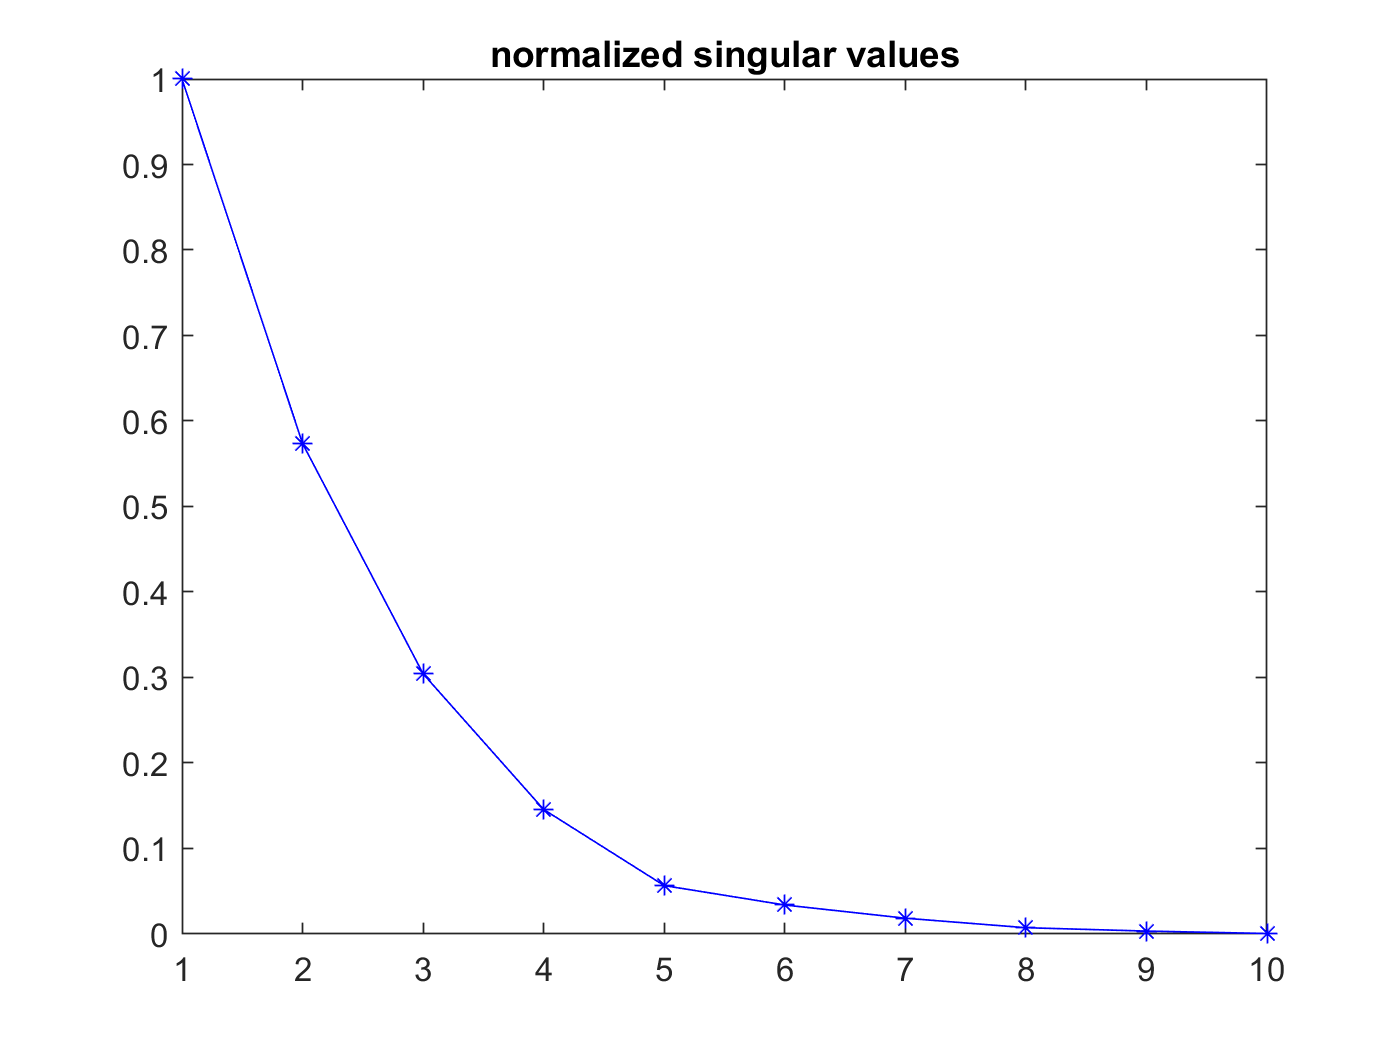

% weights (just a bunch of ones for now)
% wSHP = diag(ones(1,size(C_shp,1)));

wSHP = diag([ones(1,numel(iGap)) 4 4 0.001]); % last weight is for Ip
wPFC = diag(ones(1,size(C_shp,2)));

% SVD
[U, S, V] = svd(wSHP * C_shp * wPFC, 'econ'); 

% Show singular values
figure
plot(diag(S)/S(1,1),'*-b')
title('normalized singular values')

% Truncation
ii = find(diag(S)>S(1,1)*0.05); % keep the singular values above 5% of the largest one
SS = S(ii,ii);
UU = U(:,ii);
VV = V(:,ii);

% Compute pinv and add weights
SHP_matrix  = VV*(SS\UU');
SHP_matrix = wPFC * SHP_matrix * wSHP;

% Remove plasma current from XSC_matrix
SHP_matrix = SHP_matrix(:, 1:end-1);


Of course, this holds at steady-state: the dynamic behaviour of the shape variables will depend on the PF currents dynamics. We assigned the dynamic of the currents before, when we designed the PFC current controller, so optimistically we can design the dynamical part of our controller on the simple SISO dynamics we assigned to the currents, i.e. 


$$\frac{d}{dt}i(t)= - \lambda i(t), \quad 1/\lambda = 50ms$$


However, this approach does not always work, as the interaction with the plasma current controller must be taken into account. This time, I tuned a PID in advance for you :)

s = tf('s');
shp_contr = (0.2 + 5/s + 5*s/(1+100*s));

## Test on the full system

We are now ready to test our full magnetic control system. Let's start by extracting the necessary output matrices, loading the controller we have already tuned and initializing our ss object

% Get output matrices
i_Ip = get_y_idx(model.y_type,'Ipl',1);
C_Ip = lm.C(i_Ip,:);
D_Ip = lm.D(i_Ip,:);

D_gap = lm.D(i_gap,:);
D_xp  = lm.D(i_xp,:);

Inames = model.y_type(1:10,1);
gapnames = cell(numel(iGap),1);
for i = 1 : numel(iGap), gapnames{i} = ['Gap_' int2str(i)]; end

% Load open-loop ss model and Ip controller
load PF_contr.mat PF_clsys
load Ip_contr.mat Ip_contr

% Change output matrices
olsys = ss(PF_clsys.a,...
           PF_clsys.b,...
           [C_Ip;C_gap;C_xp],...
           [D_Ip(:,1:10);D_gap(:,1:10);D_xp(:,1:10)]);
olsys.inputname  = Inames;
olsys.outputname = [{'Ip'};gapnames;{'Rx'};{'Zx'}];

Then, we build our shape controller by assembling the decoupling matrix and the shape PID

% Build shape control
SHP_contr = shp_contr*eye(10); % turn the controller into a diagonal matrix
SHP_contr = SHP_contr*SHP_matrix;
SHP_contr.inputname  = [gapnames;{'Rx'};{'Zx'}];
SHP_contr.outputname = Inames;

Finally, we connect the Ip and shape controllers in parallel and close the loop

% Build controller
contr = parallel(Ip_contr,SHP_contr,'name');

% Close the loop
clsys = feedback(series(contr,olsys),eye(numel(iGap)+3));


For the test, let's assign some references to the gaps and the X-point position. This time, I will use another magnetic configuration as the target shape. Since the initial and target X-points are very close, to see our controller in action I added a bit of displacement on rx

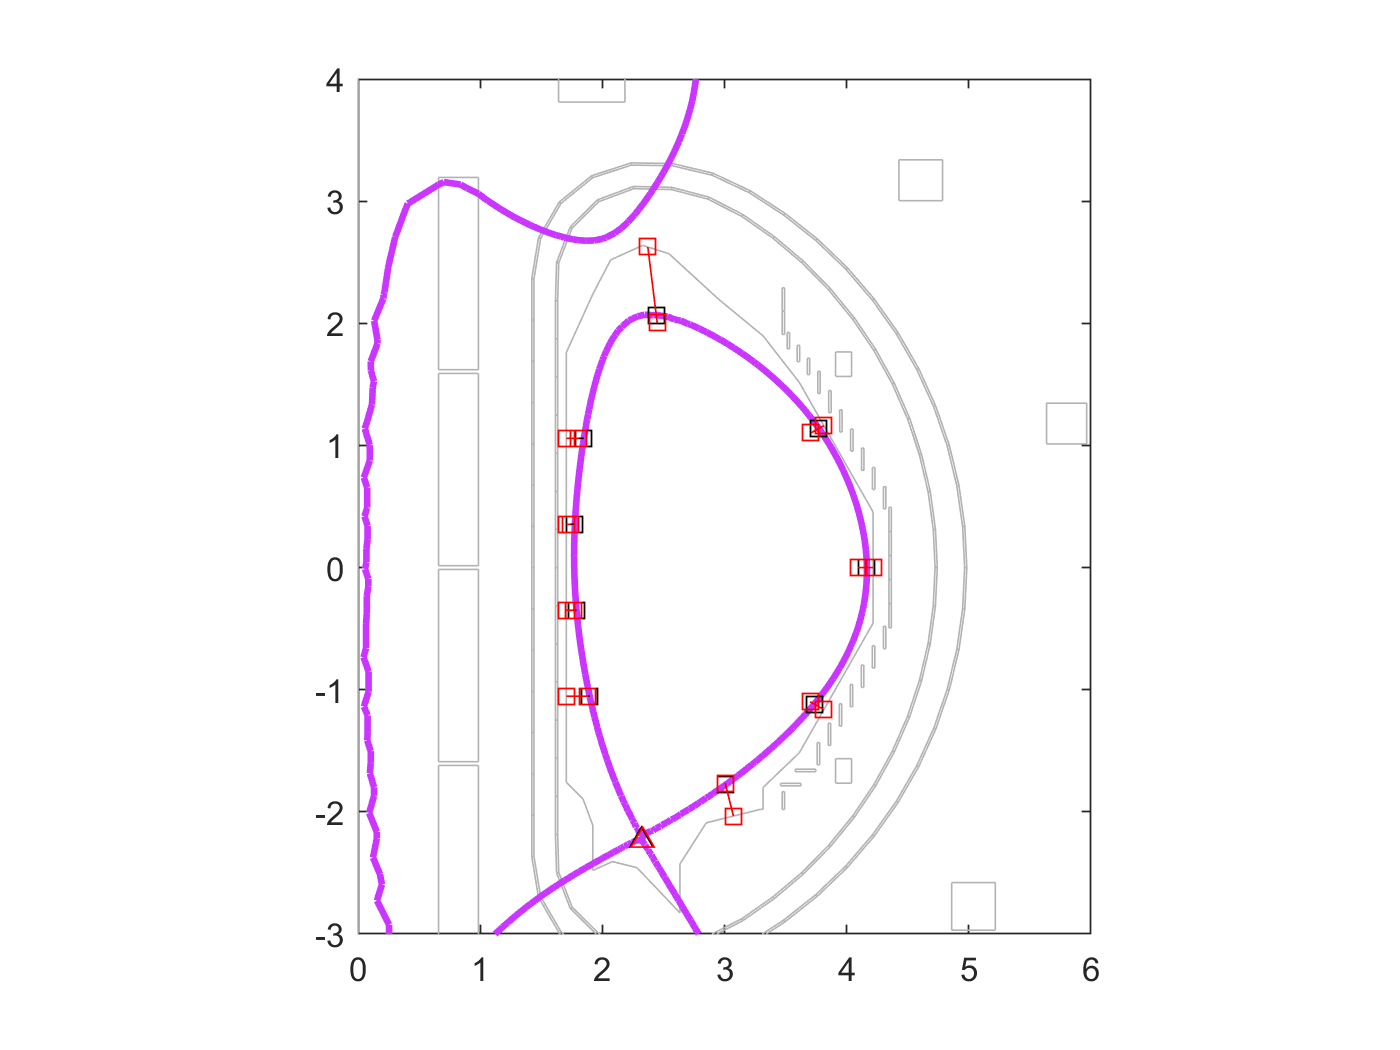

targetName = fullfile(pwd,'models','EOF@116d46s_FG.mat');
target = load(targetName);

targetGaps = target.y_np(i_gap);
initialGaps = model.y_np(i_gap);
dGap = targetGaps-initialGaps;

targetXp = target.y_np(i_xp);
initialXp = model.y_np(i_xp);
dXp = targetXp-initialXp;
dXp = dXp + [0.01; 0]; % move the x point a little

dIp = 0; % keep Ip constant

% Plot equilibrium...
figure
nnodes = size(model.Input_struct.p,2);
psib = model.y_np(get_y_idx(model.y_type,'psb_c',1));
[~,hb] = plot_plasma(model.Input_struct, model.x_np(1:nnodes), psib*[1 1]);
set(hb,'linewidth',2)
hold on
xlim([0 6])
ylim([-3 4])

% ... gaps...
for i = 1 : numel(rg)
  plot([rg(i) rg(i)+initialGaps(i)*cosd(tg(i))], [zg(i) zg(i)+initialGaps(i)*sind(tg(i))],'sk-')
  plot([rg(i) rg(i)+targetGaps(i)*cosd(tg(i))], [zg(i) zg(i)+targetGaps(i)*sind(tg(i))],'sr-')
end

% ... and x-point
plot(initialXp(1),initialXp(2),'^k')
plot(targetXp(1)+dXp(1),targetXp(2)+dXp(2),'^r')

Now we can assemble our reference and simulate the closed loop system.

dr1 = zeros(numel(iGap)+3,1);
dr2 = [dIp; dGap; dXp];

dr = [dr1 dr1 dr2 dr2]';
t  = [0 1 9 12]';

Tspan = (t(1):1e-3:t(end))';
dr = interp1(t,dr,Tspan);

[y,t] = lsim(clsys,dr,Tspan,'zoh');

Let's check the results. We start from the gaps

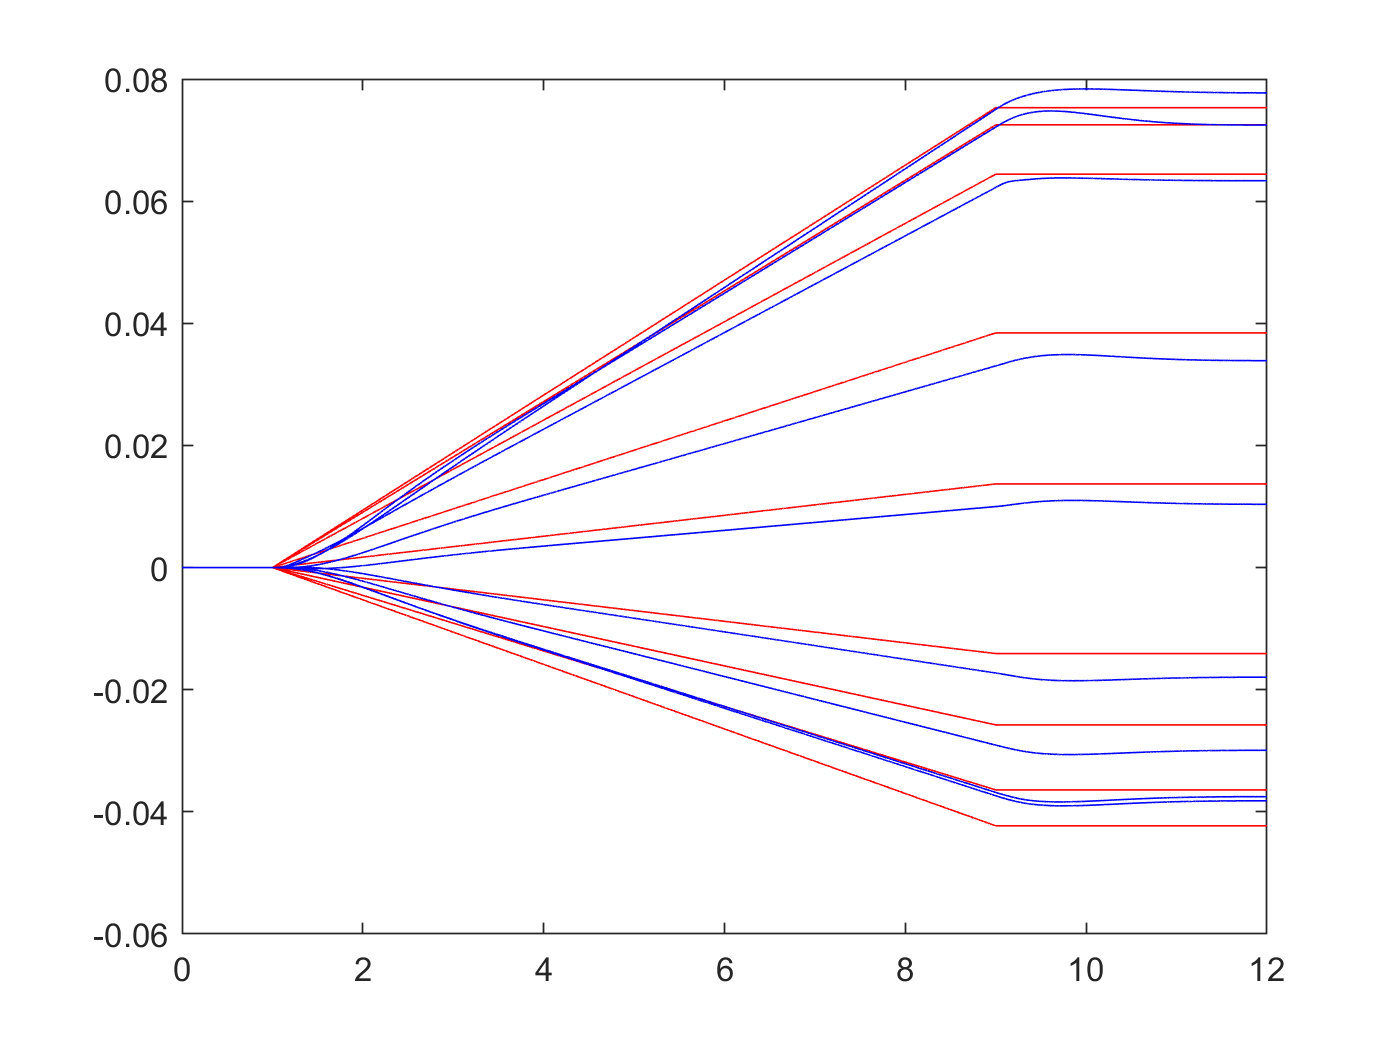

figure
plot(Tspan,dr(:,2:numel(iGap)+1),'r',t,y(:,2:numel(iGap)+1),'b')

Not too bad! We have a maximum error of a few mm. Next, the plasma current

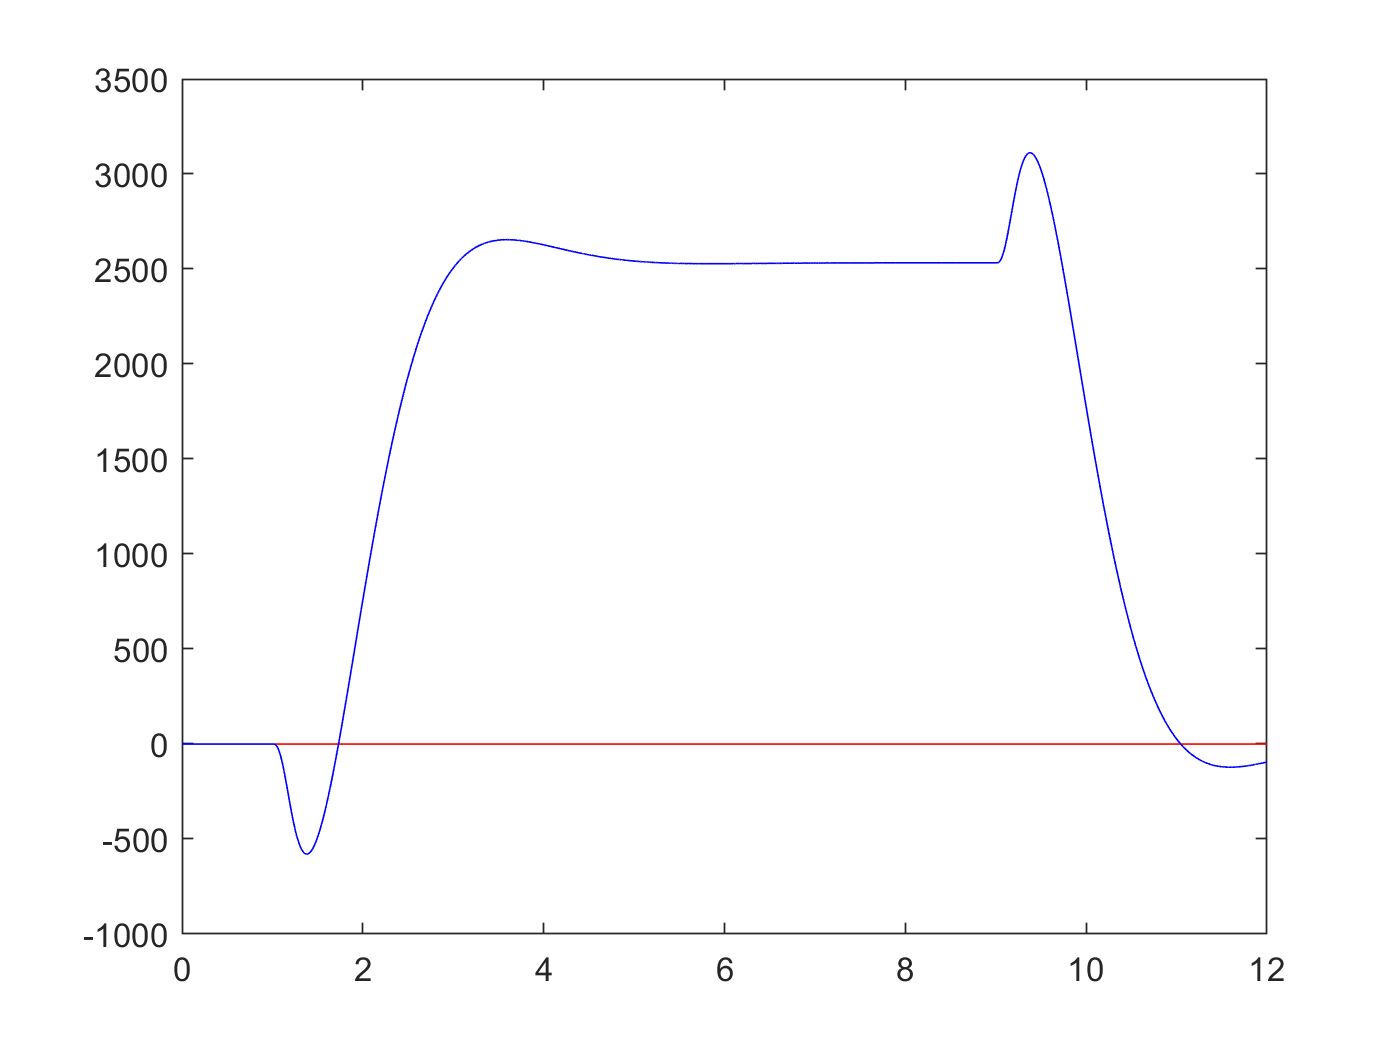

figure
plot(Tspan,dr(:,1),'r',t,y(:,1),'b')

3000 Amps might seem a lot, but the scenario current is 5.5 MA, so this is less than1/1000. Good. Finally, the X-point

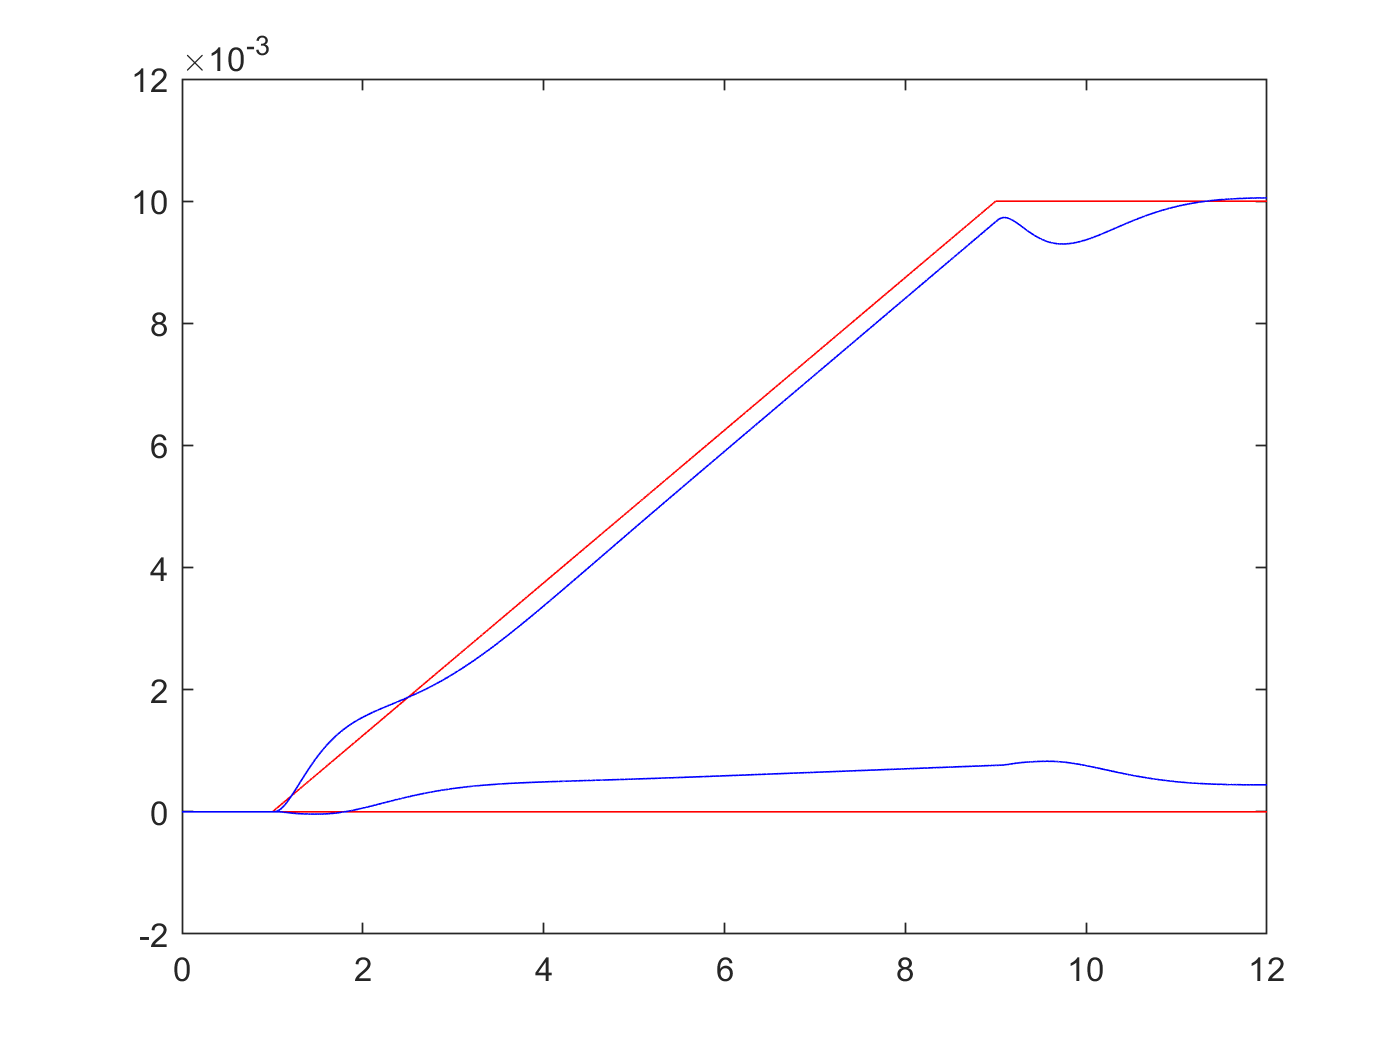

figure
plot(Tspan,dr(:,end-1:end),'r',t,y(:,end-1:end),'b')

grid on

This is quite precise, as the maximum error stays below 1mm. Actually, we chose the weight on the X-point a little higher than the one on the gaps, so we could expect this controller to be more efficient than the gap one.

Finally, let's save everything.

save ./data/shape_contr SHP_contr iGap

## Bonus: experimental results

In the past years, we also worked jointly with the EAST team on a MIMO shape control. The picture below shows some results from a few years ago (2018), where the advantage of using a MIMO shape control over a bank of SISO controllers clearly appears. Notice that at EAST an *isoflux* controller was used, which we did not discuss here. (However, it may be a good exercise to try...)